%Find the serial port that the Arduino is connected to.
serialportlist("available")

ans = "COM1"

%Connect to the Arduino Due by creating a serialport object using the port and baud rate specified in the Arduino code.
arduinoObj = serialport("COM1",9600)

arduinoObj =   Serialport with properties:

                 Port: "COM1"
             BaudRate: 9600
    NumBytesAvailable: 0

  Show all properties, functions


%Set the Terminator property to match the terminator that you specified in the Arduino code.
configureTerminator(arduinoObj,"CR/LF");
%Flush the serialport object to remove any old data.
flush(arduinoObj);
%Prepare the UserData property to store the Arduino data.
arduinoObj.UserData = struct("Data",[],"Count",1)

arduinoObj =   Serialport with properties:

                 Port: "COM1"
             BaudRate: 9600
    NumBytesAvailable: 0

  Show all properties, functions


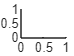


fig = figure();
ax1 = axes('Parent',fig);

% when serial port reach 50 byte, matlab read data
% configureCallback(arduinoObj,"byte",50,@readSineWaveData);
% when serial port detect terminator, matlab read data
configureCallback(arduinoObj,"terminator",@(arduinoObj, event)readSineWaveData(arduinoObj,event,ax1));

% delete(arduinoObj); 

function readSineWaveData(src, ~,ax)


% Read the ASCII data from the serialport object.
data = readline(src);

% if(src.UserData.Count==1)
%     fig = figure();
%     ax = axes('Parent',fig,'FontSize',12,'XGrid','on', 'YGrid','on', 'Box', 'on');
% end

% Convert the string data to numeric type and save it in the UserData
% property of the serialport object.
src.UserData.Data(end+1) = str2double(data);
% Update the Count value of the serialport object.
src.UserData.Count = src.UserData.Count + 1;


% animatedline(ax,src.UserData.Count,str2double(data));%ax,'MaximumNumPoints',100,'Color','m'

% addpoints();
plot(src.UserData.Data());
hold("on");
% If 1001 data points have been collected from the Arduino, switch off the
% callbacks and plot the data.
if src.UserData.Count > 200
    % configureCallback(src, "off");
    % plot(src.UserData.Data(2:end));
    % hold("on");
    % clearpoints(fig)
    % cla reset;
    
    % configureCallback(arduinoObj,"off"); %not work
    % delete(arduinoObj); %not work
end
% fclose(arduinoObj);
% delete(arduinoObj); 
end